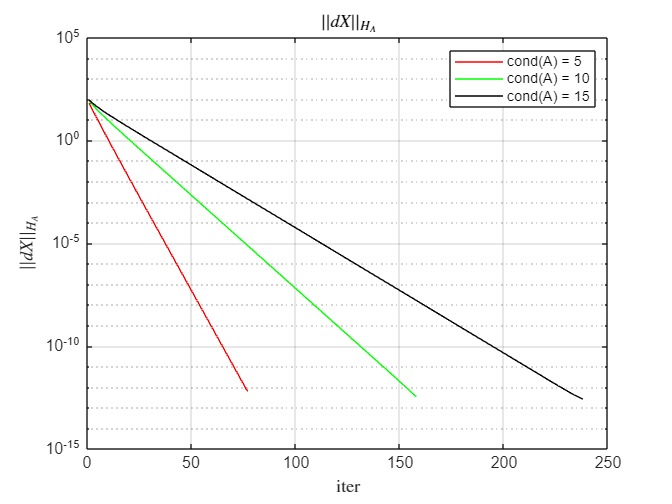

function mat = genSymMatrix(N, X, condnumber, filename)
file = fopen(filename, "w");

T = diag(linspace(1, condnumber, N));
[Q, R] = qr(rand(N));
mat = Q*T*Q';
B = mat*X;

fwrite(file, N, "int32");
fwrite(file, cond(mat), "double");
fwrite(file, mat, "double");
fwrite(file, B, "double");

fclose(file);
end

function res = HaNorm(A, X)
res = sqrt((A*X)'*X);
end

X = (1:30)';
%matrix3 = genSymMatrix(numel(X), X, 5, "grad3_SRC.bin");
% matrix10 = genSymMatrix(numel(X), X, 10, "grad10_SRC.bin");
% matrix15 = genSymMatrix(numel(X), X, 15, "grad15_SRC.bin");

T1 = readtable("grad3_Err_RES.csv");
[r1, c] = size(T1);
T2 = readtable("grad10_Err_RES.csv");
[r2, c] = size(T2);
T3 = readtable("grad15_Err_RES.csv");
[r3, c] = size(T3);

err1 = zeros(r1, 1);
iter1 = zeros(r1, 1);

for i = 1:r1
    err1(i, 1) = HaNorm(matrix3, T1{i, 2:end}' - X);
    iter1(i, 1) = T1{i, 1};
    %err(i, 1) = norm(T1{i, 1:end}' - X);
end

err2 = zeros(r2, 1);
iter2 = zeros(r2, 1);

for i = 1:r2
    err2(i, 1) = HaNorm(matrix10, T2{i, 2:end}' - X);
    iter2(i, 1) = T2{i, 1};
    %err(i, 1) = norm(T1{i, 1:end}' - X);
end

err3 = zeros(r3, 1);
iter3 = zeros(r3, 1);

for i = 1:r3
    err3(i, 1) = HaNorm(matrix15, T3{i, 2:end}' - X);
    iter3(i, 1) = T3{i, 1};
    %err(i, 1) = norm(T1{i, 1:end}' - X);
end

figure

semilogy(iter1, err1, "r-");
hold on
grid on
semilogy(iter2, err2, "g-");
semilogy(iter3, err3, "k-");
title("$||dX||_{H_A}$", Interpreter="latex");
ylabel("$||dX||_{H_A}$", Interpreter="latex");
xlabel("iter", Interpreter="latex");
legend("cond(A) = 5", "cond(A) = 10", "cond(A) = 15");

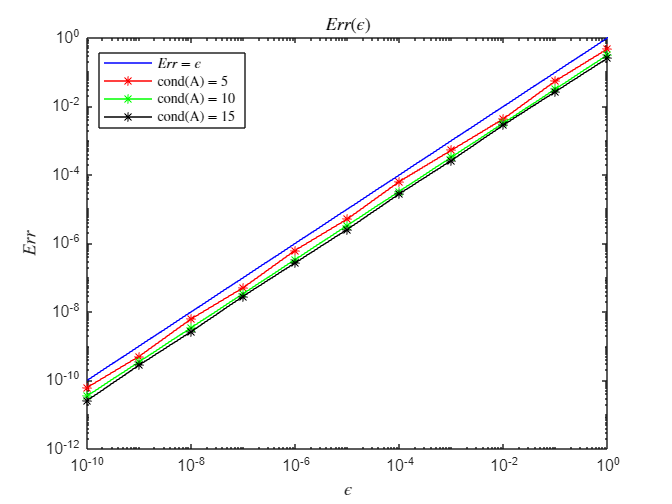

T4 = readtable("grad3_Conv_RES.csv");
[r4, c] = size(T4);

err4 = zeros(r4, 1);
eps4 = zeros(r4, 1);

for i = 1:r4
    err4(i, 1) = HaNorm(matrix3, T4{i, 2:end}' - X);
    eps4(i, 1) = T4{i, 1};
    %err(i, 1) = norm(T1{i, 1:end}' - X);
end

T5 = readtable("grad10_Conv_RES.csv");
[r5, c] = size(T5);

err5 = zeros(r5, 1);
eps5 = zeros(r5, 1);

for i = 1:r5
    err5(i, 1) = HaNorm(matrix10, T5{i, 2:end}' - X);
    eps5(i, 1) = T5{i, 1};
    %err(i, 1) = norm(T1{i, 1:end}' - X);
end

T6 = readtable("grad15_Conv_RES.csv");
[r6, c] = size(T6);

err6 = zeros(r6, 1);
eps6 = zeros(r6, 1);

for i = 1:r6
    err6(i, 1) = HaNorm(matrix15, T6{i, 2:end}' - X);
    eps6(i, 1) = T6{i, 1};
    %err(i, 1) = norm(T1{i, 1:end}' - X);
end

figure
loglog(eps4, eps4, "b-");
hold on
loglog(eps4, err4, "r-*");
loglog(eps5, err5, "g-*");
loglog(eps6, err6, "k-*");
title("$Err(\epsilon)$", Interpreter="latex");
xlabel("$\epsilon$", Interpreter="latex");
ylabel("$Err$", Interpreter="latex");
legend(["$Err = \epsilon$", "cond(A) = 5", "cond(A) = 10", "cond(A) = 15"], "Interpreter", "latex", "Position", [0.1503 0.7471 0.2136, 0.1502])

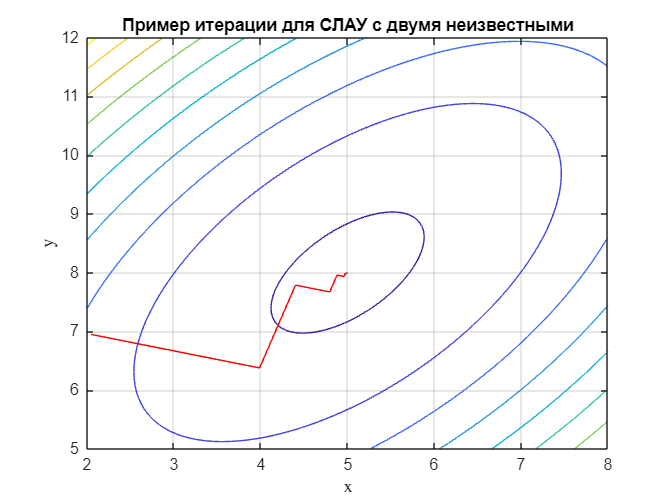


figure

T7 = readtable("grad_VIS_RES.csv");
[r7, c] = size(T7);
Xv = zeros(r7);
Yv = zeros(r7);

for i = 1:r7
    Xv(i) = T7{i, 2};
    Yv(i) = T7{i, 3};
end

%A = genSymMatrix(2, [5 8]', 4, "grad_VIS_SRC.bin");
B = A*[5;8];
x = linspace(2, 8, 1000);
y = linspace(5, 12, 1000);
Z = zeros(1000, 1000);

[X, Y] = meshgrid(x, y);

for i = 1:1000
    for j = 1:1000
        v = [X(i, j); Y(i, j)];
        Z(i, j) = dot(A*v, v) - 2*dot(B, v);
    end
end

contour(X, Y, Z);
hold on
plot(Xv, Yv, "r-");
xlim([2, 8]);
ylim([5, 12]);
xlabel("x", Interpreter="latex");
ylabel("y", Interpreter="latex");
title("Пример итерации для СЛАУ с двумя неизвестными");

grid on

sqrt([0.3571 -0.1786]*[2 1; 1 2]*[0.3571; -0.1786])

ans = 0.4374

[0.3571 -0.1786]*[2 1; 1 2]*[0.3571; -0.1786]

ans = 0.1913

2*([2 1; 1 2]*[0.3571; 0.7143] - [1; 2])

ans =     0.8570
   -0.4286


[0.3571; 0.7143] - 0.4167*[0.8570; -0.4286]

ans =    -0.0000
    0.8929


Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in lab3>genSymMatrix (line 7)
B = mat*X;

Related documentation

[0.3571; 0.7143] - [0.0000; 0.8929]